%TestAll: check functionalities of various Actors and Models

## SETUP

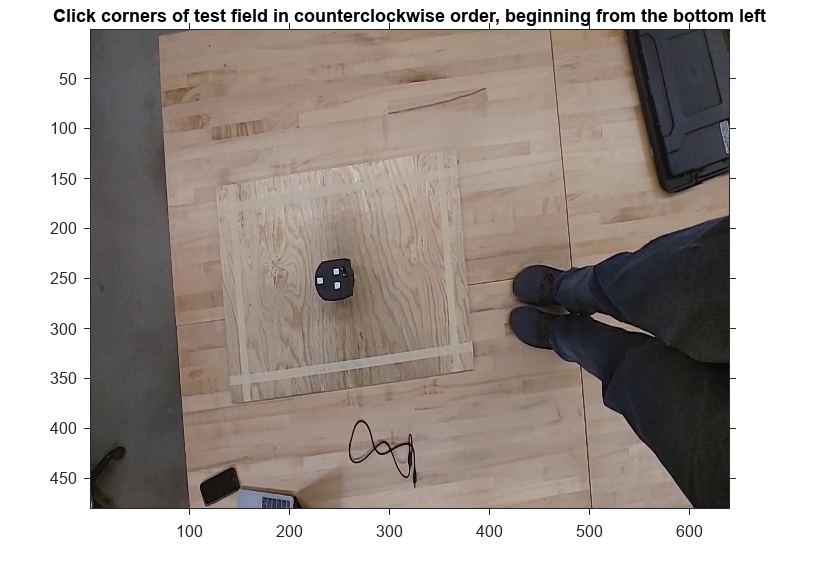

ImageConfiguration

bounds=[100 100 1000 500]

bounds =          100         100        1000         500


% initialize environment settings
environment = Environment(1,bounds);

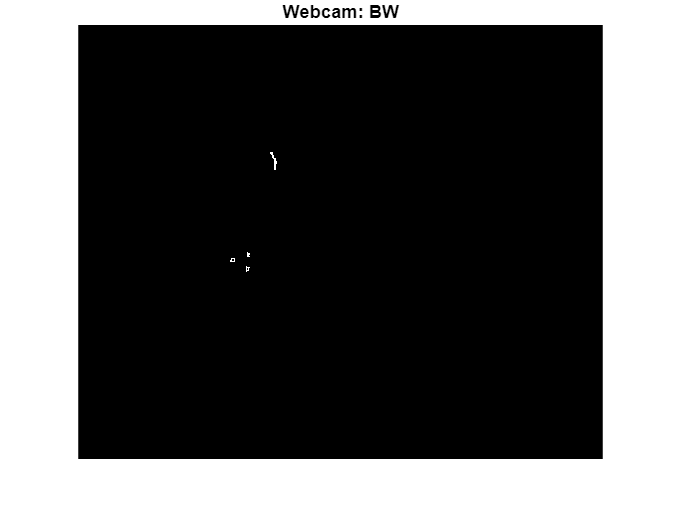

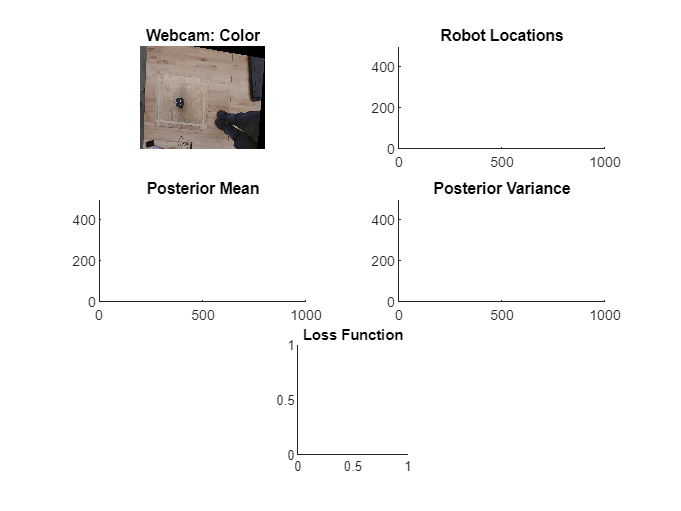

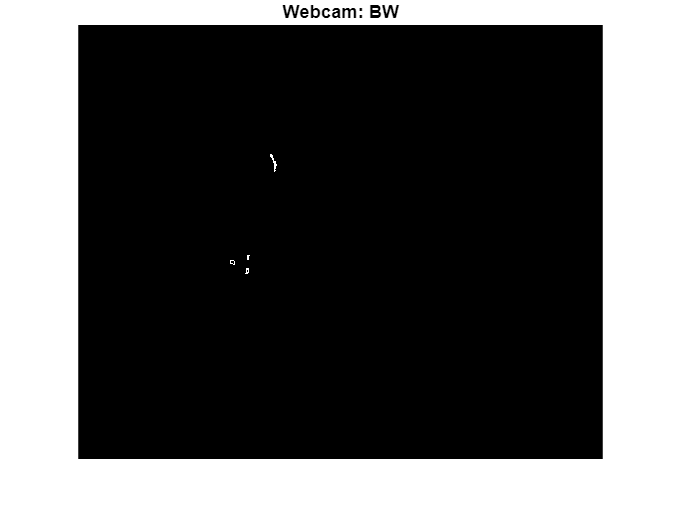


% initialize plot helper object
plotter = Plotter(environment);

% initialize webcam tracking
vision = Vision(environment, plotter, transformation, bounds);


% initialize targets and navigation
navigator = Navigator(environment, plotter);
navigator = navigator.SetTargetsFromCSV('test_path_single.csv');


% initialize communications
messenger = Messenger(environment, plotter);

## ACTION

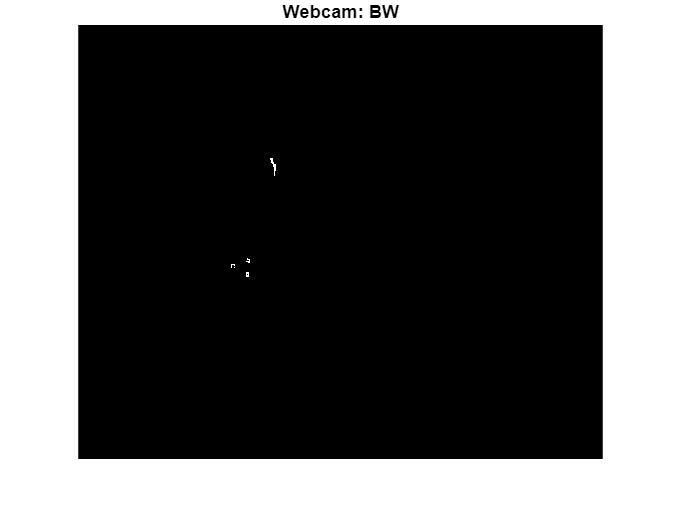

% update positions of robots in field
vision.UpdatePositions();

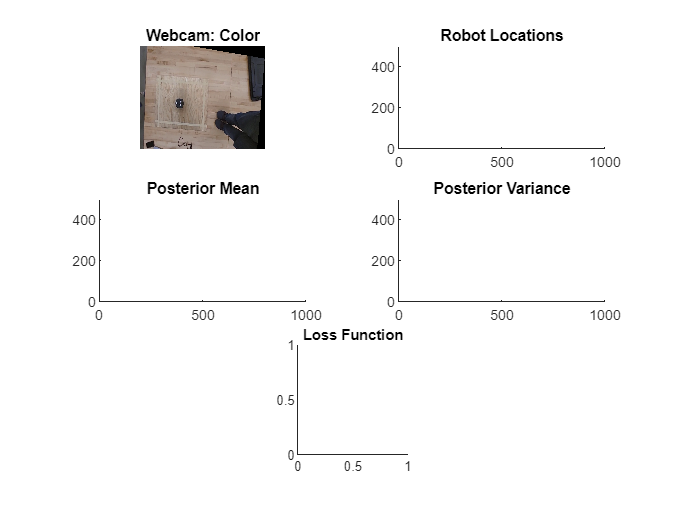

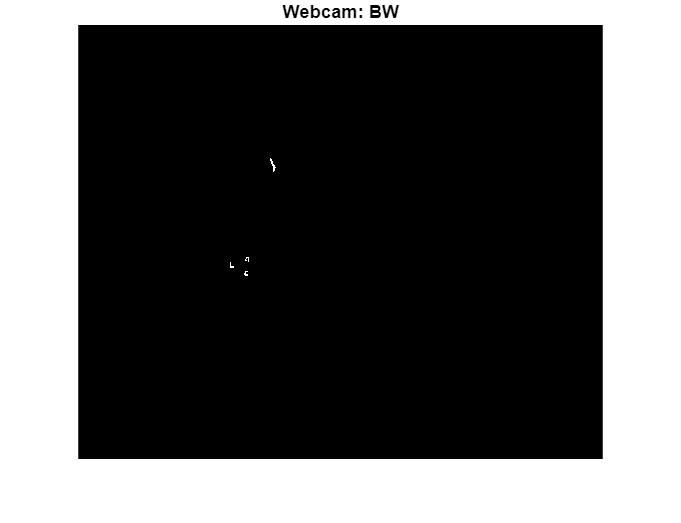


% check if robots are converged on targets
flag = navigator.IsConverged();

% get and send directions via UDP
directions = navigator.GetDirections();
messenger.SendDirections(directions);

% update targets map
navigator.UpdateTargets();

% update positions map
vision.UpdatePositions();


% get and send new directions via UDP
directions = navigator.GetDirections();
messenger.SendDirections(directions);

% test send halt command
% messenger.SendHalt();